clear; close; clc;
% ROS Setup
rosshutdown;
rosinit;

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
Initializing global node /matlab_global_node_76102 with NodeURI http://sumeet-Nitro-AN515-55:37641/ and MasterURI http://localhost:11311.


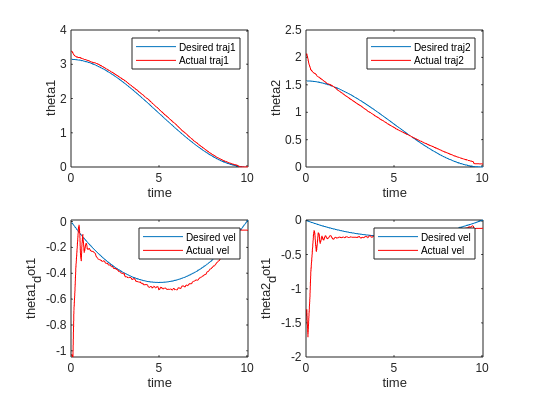

syms t0 t1 t
syms theta1 theta1_dot1 theta1_dot2 
syms theta2 theta2_dot1 theta2_dot2 

%Physical Parameters 
m1 = 1; m2=1; l1=1; l2=1 ; r1=0.45; r2=0.45; 
I1=0.084 ; I2 = 0.084 ; g = 9.81;

%Old Variables 
l1=1; l2=1 ; r1=0.45; r2=0.45; g = 9.81;   
%New Variables 
i1 = 0.063 ; i2 = 0.063 ; m1_new=0.75 ; m2_new = 0.75 ;


%Control law K values 
K = [   2     0     3     0;
         0    2     0     3];

%Values of A and B 
A1_ = [0 0 1 0;0 0 0 1;-K];
B = [  0     0 ;0     0 ;1     0 ;0    1];
%Variables
rho = 8;
phi = 0.6;

   
% Parameters tuning and defining P 
tune = eye(4)*10;
P = lyap(A1_',tune);


j1_effort = rospublisher('/rrbot/joint1_effort_controller/command');
j2_effort = rospublisher('/rrbot/joint2_effort_controller/command');

JointStates = rossubscriber('/rrbot/joint_states');

tau1 = rosmessage(j1_effort);
tau2 = rosmessage(j2_effort);

tau1.Data = 0;
tau2.Data = 0;

send(j1_effort,tau1);
send(j2_effort,tau2);

client = rossvcclient('/gazebo/set_model_configuration');
req = rosmessage(client);
req.ModelName = 'rrbot';
req.UrdfParamName = 'robot_description';
req.JointNames = {'joint1','joint2'};
req.JointPositions = [deg2rad(200), deg2rad(125)];
resp = call(client,req,'Timeout',3);

tic;
t = 0;
m = 1;

while(t < 10)
    t = toc;

    % read the joint states
    jointData = receive(JointStates);
    X = [wrapTo2Pi(jointData.Position(1));wrapTo2Pi(jointData.Position(2));jointData.Velocity(1);jointData.Velocity(2)];
    %X = [(jointData.Position(1));(jointData.Position(2));jointData.Velocity(1);jointData.Velocity(2)];
    % Desired Trajectorires
    Joint1 = (pi*t^3)/500 - (3*pi*t^2)/100 + pi;
    vel1 = (3*pi*t^2)/500 - (3*pi*t)/50;
    acc1 = (3*pi*t)/250 - (3*pi)/50;
           
    Joint2 = (pi*t^3)/1000 - (3*pi*t^2)/200 + pi/2;
    vel2 = (3*pi*t^2)/1000 - (3*pi*t)/100;
    acc2 = (3*pi*t)/500 - (3*pi)/100; 
    acc = [acc1;acc2];
    

    theta1 = X(1);
    theta2 = X(2);
    theta1_dot1 = X(3);
    theta2_dot1 = X(4);

    des_x = [Joint1;Joint2;vel1;vel2];
    x = [theta1;theta2;theta1_dot1;theta2_dot1];

    e = x - des_x;


    % Variables 
    a = i1 + i2 + m1_new*r1^2 + m2_new*(l1^2 + r2^2);
    b = m2_new*l1*r2;
    d = i2 + m2_new*r2^2;
    
    %Values of Mmat, Cmat and Gmat from the Assignment 
    Mmat = [a+2*b*cos(theta2), d+b*cos(theta2); d+b*cos(theta2), d];
    Cmat = [-b*sin(theta2)*theta2_dot1, -b*sin(theta2)*(theta1_dot1+theta2_dot1); b*sin(theta2)*theta1_dot1,0];
    Gmat = [-m1_new*g*r1*sin(theta1)-m2_new*g*(l1*sin(theta1)+r2*sin(theta1+theta2)); -m2_new*g*r2*sin(theta1+theta2)];
        
    K = [   2     0     3     0;
         0    2     0     3];
    
    %Boundary Condition 
    if phi > 0
        if norm((e')*P*B) > phi
                vr = -rho*((e')*P*B)/(norm((e')*P*B));
        else
                vr = -rho*((e')*P*B)/(phi);
        end
    else
        if norm((e')*P*B) ~= 0
                vr = -rho*((e')*P*B)/(norm((e')*P*B));
        else
                vr = 0 ;
        end
    end   
   

    V = -K*e + vr' + acc;
    U = Mmat*V + Cmat*[theta1_dot1;theta2_dot1] + Gmat;


    tau1.Data = [U(1,:)];
    tau2.Data = [U(2,:)];
    
    send(j1_effort, tau1);
    send(j2_effort, tau2);

    % you can sample data here to be plotted at the end
    act1(m) = X(1);
    act2(m) = X(2);
    actv1(m) = X(3);
    actv2(m) = X(4);

    des_1(m) = pi - (3*pi.*t.^2)/100 + (pi.*t.^3)/500;
    desv_1(m) = - (6*pi.*t)/100 + (3.*t.^2*pi)/500;
    
    des_2(m) =  pi/2 - (3*pi.*t.^2)/200 + (pi.*t.^3)/1000;
    desv_2(m) = - (6*pi.*t)/200 + (3.*t.^2*pi)/1000;
    
    torque1(m) = tau1.Data;
    torque2(m) = tau2.Data;
    
    time(m) = t;
    
    m = m + 1;
end


figure;
subplot(2, 2, 1)
plot(time, des_1);
hold on
plot(time,act1,'r');
ylabel('theta1');
xlabel('time');
legend('Desired traj1','Actual traj1')
hold off

subplot(2, 2, 2)
plot(time, des_2);
hold on
plot(time,act2,'r');
ylabel('theta2');
xlabel('time');
legend('Desired traj2','Actual traj2')
hold off


subplot(2, 2, 3)
plot(time, desv_1);
hold on
plot(time,actv1,'r');
ylabel('theta1_dot1');
xlabel('time');
legend('Desired vel','Actual vel')
hold off


subplot(2, 2, 4)
plot(time, desv_2);
hold on
plot(time,actv2,'r');
ylabel('theta2_dot1')
xlabel('time')
legend('Desired vel','Actual vel')
hold off

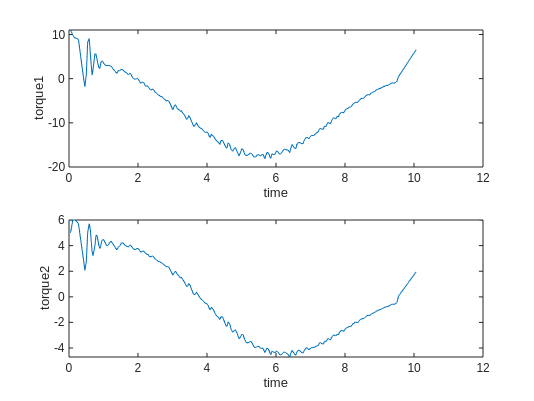



figure;
subplot(2,1,1);
plot(time,torque1);
ylabel('torque1');
xlabel('time');

subplot(2,1,2);
plot(time,torque2);
ylabel('torque2');
xlabel('time');


tau1.Data = 0;
tau2.Data = 0;
send(j1_effort,tau1);
send(j2_effort,tau2);

% disconnect from roscore
rosshutdown;

Shutting down global node /matlab_global_node_76102 with NodeURI http://sumeet-Nitro-AN515-55:37641/ and MasterURI http://localhost:11311.
